
% Lab 3 for Digital Audio Signal Processing Lab Sessions
% Session 3: Noise reduction in the STFT domain
% R.Ali, G. Bernardi, J.Schott, A. Bertrand
% 2020
%
% The following is the skeleton code for doing the noise reduction in the
% STFT domain. Complete the missing sections accordingly
clear;
close all

if ispc
    addpath('..\..\audio_files');
    addpath('..\..\sim_environment');
else
    addpath('../../audio_files');
    addpath('../../sim_environment');
end

% Load ATFs
load Computed_RIRs

% Load measured HRTFs
load HRTF
% Load binaural signal
load binaural_sig
% run session 1
%  speech = binaural_sig;
% load speech_both 
source_filename{1} = 'speech1.wav';
siglength = 5; 
[source_signals_raw{1}, source_signals_raw{2}] = audioread(source_filename{1});
signal  = resample(source_signals_raw{1},fs_RIR,source_signals_raw{2});
signal = 10*signal(1:siglength*fs_RIR);
% speech = fftfilt(RIR_sources(1:200,:),signal,siglength*fs_RIR);
speech =  fftfilt(HRTF(1:200,:),signal,siglength*fs_RIR);

## Generate noise at microphone

SNR_bubble = 5; SNR_white = 30;
noise_filename{1} = 'Babble_noise1.wav';noise_filename{2} = 'White_noise1.wav';

noise_babble = generate_noise(noise_filename{1},speech(:,1),...
    fs_RIR,SNR_bubble,RIR_noise(1:200,:),siglength);
noise_white  = generate_noise(noise_filename{2},speech(:,1),...
    fs_RIR,SNR_white,RIR_noise(1:200,:),siglength);


## Session 3 

%% Exercise 3.1: ## Obtain the noisy microphone signals as outlined in the session document.
%
% SOME CONVENTIONS:
%
% Your clean speech signal should be called "speech" and is a binaural signal such that:
% speech = [speech_L speech_R]  % speech_L and speech_R are the clean binaurally synthesised speech signals from session 1
%
% Your noises should be stored in one binaural variable called "noise"


noise = noise_white + noise_babble;
% noise = noise_white;
% Create noisy mic signals in the time domain:
y_TD = speech + noise;  % stacked microphone signals
%soundsc(y_TD,fs_RIR)
snrb = snr(speech(:,1),noise_babble(:,2));
snrw = snr(speech(:,1),noise_white(:,2));

%% Apply WOLA analysis to observe signals in the STFT domain, Apply the SPP.

fs = fs_RIR;    % sampling freq
nfft = 512;    % number of DFT points
window = sqrt(hann(nfft,'periodic')); % analysis window
noverlap = 2;   % factor for overlap. noverlap = 2 corresponds to 50% overlap
time = 0:1/fs:((size(binaural_sig,1)-1)/fs);


% ## Apply the WOLA analysis to the noisy mic. signals, the speech, and the noise.
[y_STFT,f] = WOLA_analysis(y_TD,fs_RIR,window,nfft,noverlap) ;% To complete
[n_STFT,~] = WOLA_analysis(noise,fs_RIR,window,nfft,noverlap) ;% To complete
[x_STFT,~] = WOLA_analysis(speech,fs_RIR,window,nfft,noverlap) ;% To complete
% f = squeeze(f(:,1,1));

% Observe the STFT
clow = -60; chigh = 10; % lower and upper limits for signal power in spectrogram (can change for different resolutions)
[N_freqs, N_frames] = size(y_STFT(:,:,1));

% figure;
% imagesc(time, f/1000, mag2db(abs(y_STFT(:,:,1))), [clow, chigh]); colorbar;
% axis xy; set(gca,'fontsize', 14);
% set(gcf,'color','w'); xlabel('Time Frame'); ylabel('Frequency (kHz)')

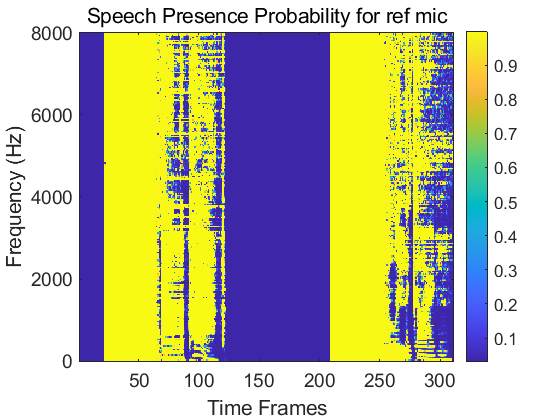


% ## Compute the Speech Presence Probability on the reference microphone
% (you can try the speech-only signal or the noisy-speech in one of the microphones)
% Use the attached spp_calc.m function

% [noisePowMat, SPP] =  spp_calc888(y_STFT(:,:,1));% To complete
[noisePowMat, SPP] =  spp_calc(speech(:,1),nfft,nfft/noverlap);

% Observe the SPP
figure; imagesc(1:N_frames, f,SPP); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('Speech Presence Probability for ref mic');

## Multi-channel 


%%  Exercise 3.2: ## Implementation of the MWF
num_mics = 2;

Rnn = cell(N_freqs,1);  Rnn(:) = {1e-8*randn(num_mics,num_mics)};      % Noise Only (NO) corr. matrix. Initialize to small random values
Ryy = cell(N_freqs,1);  Ryy(:) = {1e-8*randn(num_mics,num_mics)};      % Speech + Noise (SPN) corr. matrix. Initialize to small random values
lambda = 0.99;                                                       % Forgetting factors for correlation matrices - can change
SPP_thr = 0.95;                                                       % Threshold for SPP - can change



% For MWF filter for left ear
S_mvdr_mwfL_stft = zeros(N_freqs,N_frames,num_mics);
X_mvdr_mwfL_stft = zeros(N_freqs,N_frames,num_mics);
N_mvdr_mwfL_stft = zeros(N_freqs,N_frames,num_mics);
W_mvdr_mwfL = (1/num_mics)*ones(num_mics,N_freqs,num_mics);




% STFT Processing
% Looping through each time frame and each frequency bin
tic
for l=2:N_frames % Time index
    
    for k = 2:N_freqs % Freq index
        
        
        % Create a vector of mic. signals
        Y_kl = squeeze(y_STFT(k,l,1:num_mics));  % M x 1 noisy mic sigs for this freq and time frame
        X_kl = squeeze(x_STFT(k,l,1:num_mics));
        N_kl = squeeze(n_STFT(k,l,1:num_mics));
        
        % ## Update the correlation matrices using the forgetting factor.
        % Threshold the SPP in order to distinguish between periods of speech and non-speech activity
        if(SPP(k,l)>SPP_thr)
            Ryy{k} = lambda^2*Ryy{k}+(1-lambda^2).*Y_kl*Y_kl';
            % speech + noise
        else
            % noise only
            Rnn{k} = lambda^2*Rnn{k}+(1-lambda^2).*Y_kl*Y_kl'; % N*N' is not available in real situation
%         Ryy{k} = Rnn{k};
        end
        
        
        % Computing the MWF filter using a generalised eigenvalue
        % decomposition of the correlation matrices.
%         Rrr = rho_r(k,l)*gama{k};
        [V,d] = eig(Ryy{k},Rnn{k},'vector');
        [d,ind] = sort(abs(d),'descend','ComparisonMethod','real');
        V = V(:,ind);
        Qh = pinv(V);
%         [sig_yy,sig_nn,sig_ss,d,Q,Qh,V] = GEVD(Rnn{k},Ryy{k});
        for m = 1:num_mics
            % See DASP-CH4-37/40
            % d(1) corresponds to (d_noise/d_s&n)
            W_update = (1-1/d(1))*Qh(1,1).*V(:,m);% Final expression for filter.
%             rho_ss = sig_ss(1,1); h = Q(:,1);
%             W_single = rho_ss/(rho_ss + 1 /(h'*inv( Rnn{k})*h));
%             W_mvdr = Qh(1,1)*(1/(h'*inv( Rnn{k})*h))*pinv(Rnn{k})*h;
%             W_update2 =  W_single * W_mvdr;        
%            
%             model.weight = 4;model.power = 1;
%  [W_update3,mvdr_n1(k,l),mvdr_n2(k,l)] = weight_cal(Ryy{k}, Rnn{k},Rxx{k},1,...
%                1,TX_Mask(k,l),gama{k},h_steer(:,k),model.power,model.weight,mu);  
%      
            % After experiments, we found that Filter parameter is not likely
            % larger than 2 if it converges.
            if(max(abs(W_update)) < 2.2)  % This will skip some initial frames
                W_mvdr_mwfL(:,k,m) =W_update;
            end
            % Filtering the noisy speech, the speech-only, and the noise-only.
            S_mvdr_mwfL_stft(k,l,m) = W_mvdr_mwfL(:,k,m)'* Y_kl(1:num_mics);
            X_mvdr_mwfL_stft(k,l,m) = W_mvdr_mwfL(:,k,m)'* X_kl(1:num_mics);
            N_mvdr_mwfL_stft(k,l,m) = W_mvdr_mwfL(:,k,m)'* N_kl(1:num_mics);
        end
        
        
    end % end freqs
end % end time frames
toc
%% Observe processed STFTs

figure;
subplot(2,1,1);imagesc(time,f/1000,mag2db(abs(y_STFT(:,:,1))), [clow, chigh]); colorbar; axis xy; set(gcf,'color','w');set(gca,'Fontsize',14); xlabel('Time (s)'), ylabel('Frequency (Hz)'), title('Noise spectrum  L-Multi');
subplot(2,1,2);imagesc(time,f/1000,mag2db(abs(S_mvdr_mwfL_stft(:,:,1))), [clow, chigh]); colorbar; axis xy; set(gcf,'color','w');set(gca,'Fontsize',14); xlabel('Time (s)'), ylabel('Frequency (Hz)'),title('filtered spectrogram L-Multi');

% figure;
% subplot(2,1,1);imagesc(time,f/1000,mag2db(abs(y_STFT(:,:,2))), [clow, chigh]); colorbar; axis xy; set(gcf,'color','w');set(gca,'Fontsize',14); xlabel('Time (s)'), ylabel('Frequency (Hz)'), title('Noise spectrum  R-Multi');
% subplot(2,1,2);imagesc(time,f/1000,mag2db(abs(S_mvdr_mwfL_stft(:,:,2))), [clow, chigh]); colorbar; axis xy; set(gcf,'color','w');set(gca,'Fontsize',14); xlabel('Time (s)'), ylabel('Frequency (Hz)'),title('filtered spectrogram R-Multi');
%% EVALUATION
s_mwfL = WOLA_synthesis(S_mvdr_mwfL_stft,window,nfft,noverlap);% To complete (time-domain version of S_mvdr_mwfL_stft)
x_mwfL = WOLA_synthesis(X_mvdr_mwfL_stft,window,nfft,noverlap);% To complete (time-domain version of X_mvdr_mwfL_stft)
n_mwfL = WOLA_synthesis(N_mvdr_mwfL_stft,window,nfft,noverlap);% To complete (time-domain version of N_mvdr_mwfL_stft)

SNR_in_L =snr(speech(:,1),noise(:,1)) ;% Compute input SNR
SNR_in_R =snr(speech(:,2),noise(:,2)); % Compute input SNR
SNR_out_L =snr(s_mwfL(:,1),n_mwfL(:,1)) ;% Compute output SNR
SNR_out_R =snr(s_mwfL(:,2),n_mwfL(:,2));
delta_SNR = SNR_out_L - SNR_in_L
soundsc(real(s_mwfL(:,1)),fs_RIR)
figure;
subplot(2,1,1);
plot(speech); title('clean signal');
subplot(2,1,2);
plot(real(s_mwfL(:,1)));title('signal after enhancement');

## Function

function [sig_yy,sig_nn,sig_ss,d,Q,Qh,V] = GEVD(Rnn,Ryy)
    % Computing the MWF filter using a generalised eigenvalue
    % decomposition of the correlation matrices.

    [V,d] = eig(Ryy,Rnn,'vector');
    [d,ind] = sort(d,'descend','ComparisonMethod','real');
    V = V(:,ind);
    Qh = pinv(V);
    sig_yy = V'*Ryy *V;
    sig_yy = [sig_yy(1,1) 0;0 sig_yy(2,2)];
    sig_nn = V'*Rnn*V;
    sig_nn = [sig_nn(1,1) 0;0 sig_nn(2,2)];
    Q= Qh';
    sig_ss = sig_yy(1,1) - sig_nn(1,1) ; 
    sig_ss = [sig_ss 0; 0 0];
end
